# Testeo y Comparación con el Metodo de las Potencias Iteradas

A continuación se ensaya el metodo de las potencias con las siguientes matrices propuestas. 

Se utilizará la función ***power_iteration ***en cada una de las matrices a definir, utilizando una tolertancias de ***1e-10 ***y un numero de iteraciónes de ***30***. La función ***power_iteration *** arroja como resultado una matrix de tamaño (***30+1)x(# de columbnas de la matrix+2) ***En la primera columna se guarda la aproximación del posible $\lambda \;$***valor propio dominate de la matrix***, es de notar que la primera fila no tiene una aproximación a $\lambda$, pues el vector inicial se escoje al azar y no proviene de operar la matrix con un vector.  La segunda columna es un vector de ceros a excepción posiblemente de la ultima fila que actualiza la información de la matrix que devuelve ***power_iteration***, en está posición se actualiza su valor a la tolerancia asignada, lo anterior pasa  si la norma de la diferencias de las dos ultimas aproximaciones del valor propio está por debajo de la tolerancia. El resto de columnas se refieren a las componentes de las aproximaciones del vector, así la columna tres guarda la primera componente de cada una de las iteraciones del vector. Entonces la (i+1)_esima fila se puede leer como: Sea $\nu \;$el vector al que converge el metodo de potencias y sea $v_i$ la i_esima aproximacíon de $\nu \ldotp$ 


$$\left\lbrack \begin{array}{cccccc}
\textrm{la}\;\;i\;\textrm{esima}\;\textrm{aproximación}\;\textrm{de}\;\lambda \;\;\;\; & 0\;o\;\textrm{la}\;\textrm{tolerancia}\;\textrm{asignada} & \textrm{primera}\;\textrm{componente}\;\textrm{de}\;v_i  & \textrm{segunda}\;\textrm{componente}\;\textrm{de}\;v_i  & \ldotp \ldotp \ldotp  & \textrm{ultima}\;\textrm{componente}\;\textrm{de}\;v_i 
\end{array}\right\rbrack$$


Puede que en algunos problemas importe más tener un control sobre la aproximación de $\lambda$, por lo tanto se propone una función alternativa ***power_iteration2***, el cual tiene como criterio de parada el valor absoluto de la diferencia de la aproximacion de $\lambda$ con una aproximación anterior. En este caso, la salida de la función es la misma de ***power_iteration***, difiere unicamente en la interpretación de la columna dos, la cual es de ceros en sus componentes a excepción posiblemente de la ultima fila que actualiza la información de la matrix que devuelve ***power_iteration2*** , en está posición se actualiza su valor a la tolerancia asignada, lo anterior pasa  si el criterio de parada se cumple.

Tanto para ***power_iteration ***como para ***power_iteration2 ***la matriz que devuelven se deja de actualizar si su criterio de parada se cumple, si no se cumple la matriz actualiza todas sus filas hasta llegar al numero de iteraciones. El criterio de parada de ***power_iteration ***es la norma infinito de la diferencia de la aproximación actual y anterior del multiplo escalar del vector propio dominate. 

num_iterations= 30 % Número de iteraciones

num_iterations =     30


tol=1e-10 % Tolerancia el valor propio

tol =      1.000000000000000e-10


A=[2, 1; 3, 4]

A =      2     1
     3     4


*Tomado de: api.wolframcloud.com*

v_A= power_iteration(A, num_iterations, tol)

v_A =                    0                   0   0.984063724379154   0.167168409914656
   2.716540100044567                   0   0.507969848616707   0.861374850396922
   5.234143075226092                   0   0.353397649365586   0.935473196528301
   5.072596317636207                   0   0.323590606063148   0.946197188575238
   5.015300326160602                   0   0.317697337502111   0.948192175534089
   5.003089321918199                   0   0.316521559309979   0.948585316401208
   5.000619018927399                   0   0.316286519826270   0.948663711425807
   5.000123849841739                   0   0.316239516584684   0.948679381113707
   5.000024771809594                   0   0.316230116122645   0.948682514678677
   5.000004954435561                   0   0.316228236037689   0.948683141376767


La información mas relevante de esta matriz es su ultima fila, donde su primera entrada es la mejor aproximación de $\lambda_1$ de la matrix $A$ asociada a la mejor aproximación del multiplo escalar del vector propio dominante $v$, esta aproximación tiene su primera componentes en la tercera columna de la ultima fila v_A, y su segunda componente en su cuarta columna de la ultima fila de v_A. La segunda componete de la ultima fila coresponde a la tolerancia, y nos indica que el criterio de parada se cumplio con el vector aproximado de  $v$ en esa ultima fila y la aproximación de $v$ anterior, que coresponde al vector asociado a la fila anterior.

v_A2 = power_iteration2(A,num_iterations,tol)

v_A2 =                    0                   0   0.106216344928664   0.372409740055537
   4.904576540254171                   0   0.307728868515300   0.951474089758777
   4.981790067216959                   0   0.314523846791317   0.949249571924893
   4.996396007306498                   0   0.315886818315466   0.948796879218377
   4.999280745644810                   0   0.316159569936363   0.948706027353919
   4.999856211092309                   0   0.316214126539248   0.948687844434101
   4.999971244698564                   0   0.316225038110861   0.948684207348148
   4.999994249038930                   0   0.316227220435224   0.948683479910877
   4.999998849811756                   0   0.316227656900498   0.948683334422620
   4.999999769962509                   0   0.316227744193569   0.948683305324936


Este el el método alternativo. Su interpretanción difiere en la columna dos. la cual cambia su entrada de 0 a la tolerancia si el criterio de parada se cumplio con la aproximación de lambda en esa iteración con respecto al anterior.

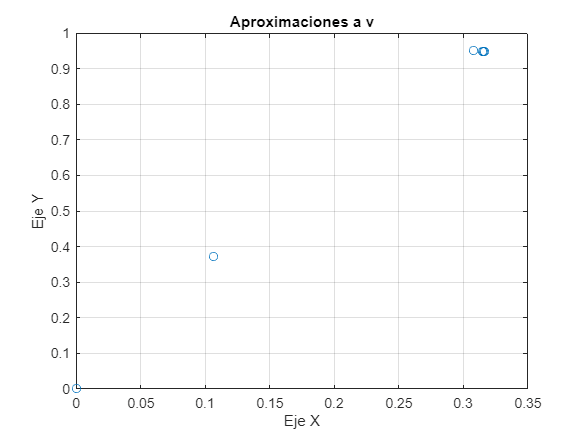

% Grafiquemos los vectores aproximados
x = v_A2(:,3); % Coordenadas en X
y = v_A2(:,4); % Coordenadas en Y

% Dibujar los puntos
plot(x, y, 'o'); % 'o' dibuja círculos para cada punto
grid on; % Agrega una cuadrícula para mayor claridad
xlabel('Eje X');
ylabel('Eje Y');
title('Aproximaciones a v');

B=[3 2; 3 4]

B =      3     2
     3     4


*Tomado de: api.wolframcloud.com*

v_B = power_iteration(B,num_iterations,tol)

v_B =                    0                   0   0.744074260367462   0.500022435590201
   5.625821962238033                   0   0.606951547370043   0.794738837068575
   6.043449653714310                   0   0.563491452082044   0.826121893808940
   6.010040511126308                   0   0.556167225656017   0.831070404421965
   6.001748622867033                   0   0.554944749491820   0.831887206904554
   6.000293513216953                   0   0.554740956436209   0.832023119421714
   6.000048976477439                   0   0.554706989630712   0.832045765360796
   6.000008164346180                   0   0.554701328460503   0.832049539513215
   6.000001360768804                   0   0.554700384931137   0.832050168533874
   6.000000226796034                   0   0.554700227676215   0.832050273370519


v_B2 = power_iteration2(B,num_iterations,tol)

v_B2 =                    0                   0   0.479922141146060   0.904722238067363
   5.850274459158848                   0   0.540430156572405   0.841388879096418
   5.981494864208912                   0   0.552325969469459   0.833628228558524
   5.997108621028094                   0   0.554304615274823   0.832313879185629
   5.999523516434460                   0   0.554634269540584   0.832094241688514
   5.999920736690359                   0   0.554689208541147   0.832057619355773
   5.999986793633419                   0   0.554698364947236   0.832051515186929
   5.999997799055159                   0   0.554699891012305   0.832050497813046
   5.999999633179089                   0   0.554700145356410   0.832050328250387
   5.999999938863271                   0   0.554700187747093   0.832050299989935


C=[2 3; 1 4]

C =      2     3
     1     4


*Tomado de: api.wolframcloud.com*

v_C = power_iteration(C,num_iterations,tol)

v_C =                    0                   0   0.609866648422558   0.617666389588455
   5.012545994246461                   0   0.706209901037128   0.708002525191210
   5.002528724351542                   0   0.706927586778608   0.707285930194694
   5.000506517282740                   0   0.707070949567638   0.707142610989833
   5.000101334284317                   0   0.707099615153255   0.707113947147218
   5.000020268089424                   0   0.707105347991508   0.707108214378682
   5.000004053667183                   0   0.707106494548005   0.707107067824974
   5.000000810735409                   0   0.707106723858857   0.707106838514233
   5.000000162147161                   0   0.707106769721010   0.707106792652085
   5.000000032429436                   0   0.707106778893440   0.707106783479655


v_C2 = power_iteration2(C,num_iterations,tol)

v_C2 =                    0                   0   0.859442305646212   0.805489424529686
   4.931061015002407                   0   0.711734445963594   0.702448630455563
   4.986695704118494                   0   0.708037214372299   0.706175122093602
   4.997359671352520                   0   0.707293064149727   0.706920449135325
   4.999472765127482                   0   0.707144045634719   0.707069514774440
   4.999894586337027                   0   0.707114234390423   0.707099327904111
   4.999978918600484                   0   0.707108271839892   0.707105290530060
   4.999995783773425                   0   0.707107079317719   0.707106483055250
   4.999999156756818                   0   0.707106840812802   0.707106721560288
   4.999999831351450                   0   0.707106793111799   0.707106769261296


D=[1 1 2; 2 1 1; 1 1 3]

D =      1     1     2
     2     1     1
     1     1     3


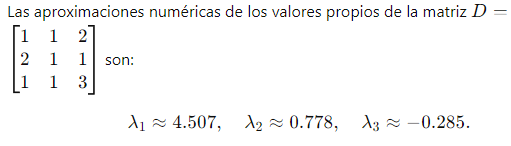*Tomado de: api.wolframcloud.com*

v_D = power_iteration(D,num_iterations,tol)

v_D =                    0                   0   0.576721515614685   0.182922469414914   0.239932010568717
   3.205953056928166                   0   0.497403968907616   0.632554718771931   0.593686634070799
   4.285818149883101                   0   0.534778328257240   0.512558860482338   0.671785348282797
   4.491335021677686                   0   0.532278418624765   0.501777084630299   0.681835348457556
   4.504091653952150                   0   0.532341203407795   0.499136696571480   0.683721727963980
   4.506544843455038                   0   0.532319353143954   0.498728096510255   0.684036835279840
   4.506935551878919                   0   0.532317598612573   0.498654485450983   0.684091863967815
   4.507004399021272                   0   0.532317166636152   0.498641968677724   0.684101323765466
   4.507016178944042                   0   0.532317100179133   0.498639795482988   0.684102959515279
   4.507018218874805                   0   0.532317088190377   0.498639421057710   0.


v_D2 = power_iteration2(D,num_iterations,tol)

v_D2 =                    0                   0   0.886511933076101   0.028674152464106   0.489901388512224
   2.838140345309960                   0   0.497132526007630   0.601179576497129   0.625653553005180
   4.364840970813154                   0   0.534747402289082   0.505497434857169   0.677139246461096
   4.498855102010371                   0   0.532235251062567   0.500585545260792   0.682744278190833
   4.505252869372129                   0   0.532335158753334   0.498927772521125   0.683878904896307
   4.506741811705079                   0   0.532318187576024   0.498692178886568   0.684063928220999
   4.506969339350679                   0   0.532317404151909   0.498648273303147   0.684096543456231
   4.507010233766161                   0   0.532317132606088   0.498640896825504   0.684102131517721
   4.507017185827170                   0   0.532317094332004   0.498639610387913   0.684103098980061
   4.507018392728773                   0   0.532317087179086   0.498639389104250   0

E=[1 1 2; 2 1 3; 1 1 1]

E =      1     1     2
     2     1     3
     1     1     1


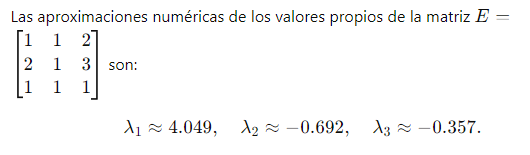*Tomado de: api.wolframcloud.com*

v_E = power_iteration(E,num_iterations,tol)

v_E =                    0                   0   0.167927145682257   0.978680649641159   0.712694471678914
   3.437891221414378                   0   0.548441977028551   0.736222098821115   0.396469947209681
   4.031207341885764                   0   0.514942669699835   0.749142967668768   0.416675966327359
   4.049589222658660                   0   0.517934995872608   0.747986131268369   0.415042271920126
   4.048902786760955                   0   0.517672485564518   0.748099658486888   0.415165146250568
   4.048910165017324                   0   0.517695466277944   0.748087743078305   0.415157961324688
   4.048919411243670                   0   0.517693468084022   0.748089120071906   0.415157971780838
   4.048916910861157                   0   0.517693639524876   0.748088942862039   0.415158077318803
   4.048917419359899                   0   0.517693625214983   0.748088968025198   0.415158049820502
   4.048917325297470                   0   0.517693626339280   0.748088964176155   0.

v_E2 = power_iteration2(E,num_iterations,tol)

v_E2 =                    0                   0   0.500471624154843   0.471088374541939   0.059618867579639
   2.910187601206895                   0   0.488866800587938   0.739884599979601   0.462147195161823
   4.130642684183288                   0   0.520206116949321   0.749984461648933   0.408544860662412
   4.033631309927890                   0   0.517450918667852   0.747694574297892   0.416169881581177
   4.051400045476218                   0   0.517718191949040   0.748161991855981   0.414995792348680
   4.048500149431422                   0   0.517690909016102   0.748075972472607   0.415184852964610
   4.048987912979832                   0   0.517693959870338   0.748091229869692   0.415153556778477
   4.048905339196003                   0   0.517693580773285   0.748088573612953   0.415158815943817
   4.048919385043470                   0   0.517693633026065   0.748089031897811   0.415157924985746
   4.048916990395851                   0   0.517693625200848   0.748088953192148   0

F=[2 1 2; 1 1 3; 1 1 1]

F =      2     1     2
     1     1     3
     1     1     1


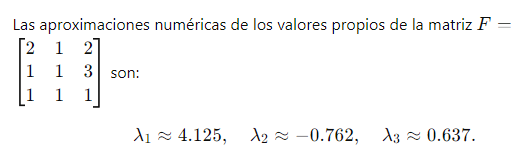*Tomado de: api.wolframcloud.com*

v_F = power_iteration(F,num_iterations,tol)

v_F =                    0                   0   0.681971904149063   0.042431137500742   0.071445464600642
   2.443369653296584                   0   0.783013820625538   0.474447907093318   0.402229462078759
   4.064310569561949                   0   0.691621867013293   0.599050740495930   0.403481602282342
   4.110967897808901                   0   0.678378369220144   0.608299464585270   0.412037073040147
   4.126630446071530                   0   0.675880378760691   0.611338807155958   0.411643749462366
   4.124479090438451                   0   0.675573021823700   0.611507572890410   0.411897536386994
   4.124949386625601                   0   0.675510997364595   0.611588883589037   0.411878537811582
   4.124871927089564                   0   0.675504113348025   0.611591229700260   0.411886344279125
   4.124887652405257                   0   0.675502554189215   0.611593475619737   0.411885566466242
   4.124884967684963                   0   0.675502405220854   0.611593474477771   0.

v_F2 = power_iteration2(F,num_iterations,tol)

v_F2 =                    0                   0   0.521649842464284   0.096730025780867   0.818148553859625
   3.071801237481230                   0   0.633378421265918   0.701020272536600   0.327722982055585
   3.830870263263804                   0   0.676973360849540   0.598093073623311   0.428942588214203
   4.165417568239620                   0   0.674352553564764   0.614827766756999   0.408944312499004
   4.117011913254952                   0   0.675582952659632   0.611117612461710   0.412459619617232
   4.126331022953710                   0   0.675467289097084   0.611700416012237   0.411784582531076
   4.124619550856310                   0   0.675505723929672   0.611576748375574   0.411905204852535
   4.124934725435433                   0   0.675501260037925   0.611597092700320   0.411882318008060
   4.124876353140967                   0   0.675502490303933   0.611592952306650   0.411886448286442
   4.124887099387992                   0   0.675502325845292   0.611593657397989   0


G=[1 1 1 2; 2 1 1 1; 3 2 1 2; 2 1 1 4]

G =      1     1     1     2
     2     1     1     1
     3     2     1     2
     2     1     1     4


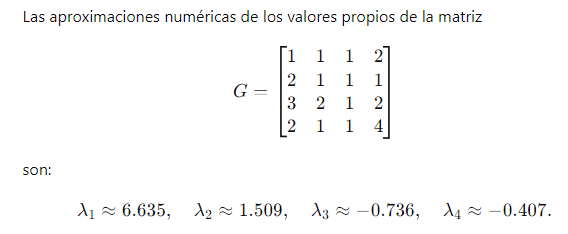*Tomado de: api.wolframcloud.com*

v_G = power_iteration(G,num_iterations,tol)

v_G =                    0                   0   0.817547092079286   0.722439592366842   0.149865442477967   0.659605252908307
   5.429223742361053                   0   0.348938811835462   0.367254162635998   0.622324625042507   0.596722839086197
   6.392191799961033                   0   0.394619933189643   0.356001475670584   0.560626382830840   0.635008753108000
   6.637337561124322                   0   0.388887800708910   0.352671345326017   0.561427363826195   0.639678447184907
   6.629985389098695                   0   0.389493517457092   0.351666894212007   0.559998244622539   0.641114000310286
   6.634082956871535                   0   0.389411239402835   0.351482792329365   0.559842307744331   0.641401063128681
   6.634368740449592                   0   0.389417373955959   0.351434887253920   0.559788559170324   0.641470496518805
   6.634503779839518                   0   0.389415983256177   0.351424728616653   0.559778330226114   0.641485832353763
   6.634526714866351      

v_G2 = power_iteration2(G,num_iterations,tol)

v_G2 =                    0                   0   0.518594942510538   0.972974554763863   0.648991492712356   0.800330575352401
   6.028567105169762                   0   0.387139004606470   0.357985201822546   0.595149390263445   0.606438116923262
   6.535916832665466                   0   0.390276376155815   0.356754151245451   0.563354970123091   0.634855891853760
   6.626218022910265                   0   0.389367310868638   0.352457358281349   0.561000424818097   0.639879231710308
   6.631539577948423                   0   0.389438896256929   0.351663124908633   0.560016206289279   0.641133559685534
   6.633981139057789                   0   0.389417019226416   0.351476808058156   0.559833668340372   0.641408374069614
   6.634395639056223                   0   0.389416666425727   0.351434102895804   0.559788001437913   0.641471842466871
   6.634504347477196                   0   0.389416046755979   0.351424485851069   0.559778047641924   0.641486173390708
   6.634527458518647     


H=[1 2 1 2; 2 1 1 1; 3 2 1 2; 2 1 1 4]

H =      1     2     1     2
     2     1     1     1
     3     2     1     2
     2     1     1     4


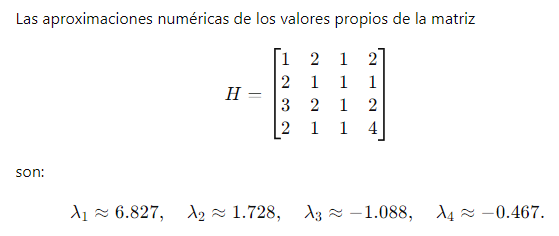*Tomado de: api.wolframcloud.com*

v_H = power_iteration(H,num_iterations,tol)

v_H =                    0                   0   0.453797708726919   0.432391503783462   0.825313795402046   0.083469814858914
   4.519703073025616                   0   0.444711074353760   0.432767173167113   0.619374294851066   0.480957500257367
   6.535202669722010                   0   0.438582353807092   0.367443284611097   0.573488172970375   0.586295375204632
   6.782219878803522                   0   0.430217170603865   0.354305043093306   0.559473938609059   0.613490044396421
   6.816433161684634                   0   0.429134090729840   0.350272269199762   0.555358433886929   0.620266297257702
   6.824963027483295                   0   0.428656159236236   0.349329262144162   0.554410109859846   0.621974592603144
   6.826633815644093                   0   0.428567516719305   0.349077738630408   0.554150959737655   0.622407687796001
   6.827112859822522                   0   0.428539758964861   0.349015966799793   0.554088441441266   0.622517091304595
   6.827222988509934      

v_H2 = power_iteration2(H,num_iterations,tol)

v_H2 =                    0                   0   0.133171007607162   0.173388613119006   0.390937802323736   0.831379742839070
   5.803372052904797                   0   0.432640058557878   0.283807901660677   0.478120069105977   0.709701947442795
   6.885663812719863                   0   0.418414577980009   0.337429785892726   0.543353612963002   0.644854426833105
   6.837277333542321                   0   0.427895672949733   0.345445357608792   0.550258757506502   0.628321651516825
   6.834433486147627                   0   0.428073016964891   0.348203682328559   0.553288394389467   0.624002916975020
   6.828524010419570                   0   0.428463273734997   0.348777963990289   0.553841056166984   0.622923140843971
   6.827682500402257                   0   0.428506501568437   0.348942492199902   0.554014166807956   0.622647266296888
   6.827353307251017                   0   0.428526259259940   0.348981048946880   0.554052647167979   0.622577815832506
   6.827287788667316     

### Conclusiones

- Como se pudo observar, este metodo fue basta bueno prediciendo los valores propios de las matrices propuestas. Lo anterior ocurre ya que todas las matrices anteriormente definidas tienen vector propio domiante, y son diagonalizables con lo cual podemos decir que las aproximaciones a los multiplos escalares de los vectores propios domiantes de las matrices son buenas, y a su vez sus valores propios son buenas. 

- En la investigacion de este método algunas personas mencionan que si la norma del valor propio domiante es cercana a la norma de otro valor propio dominante el metodo puede volverse muy lento o fallar.

- Este meto es usado para solucionar problemas que requieran el radio espectral de la matriz, este tipo de problemas surgen en fisica y algunos pasos de modelado epidemiologico. De hecho, este algoritmo se utiliza para calcular el Google PageRank.

- Sin embargo es curiso saber que tambien funciona en otras matrices que no cumplen la condición, por ejemplo:

T=[3,0 ;0,3]

T =      3     0
     0     3


v=power_iteration(T, num_iterations, tol)

v =                    0                   0   0.803364391602440   0.060471179169894
   3.000000000000000                   0   0.997179013652695   0.075060074144898
   3.000000000000000   0.000000000100000   0.997179013652695   0.075060074144898
                   0                   0                   0                   0
                   0                   0                   0                   0
                   0                   0                   0                   0
                   0                   0                   0                   0
                   0                   0                   0                   0
                   0                   0                   0                   0
                   0                   0                   0                   0


- El metodos de las potencias tambien se podría pensar como un sistema dinamico y el espacio de estado que dibuja converge no solo a un punto sino al espacio generado por el vector propio dominate de la matriz asociada que se este estudiando. 

% Metodo de las potencias alternativa
 function M = power_iteration2(A, num_iterations, tol)
     
     format long % Muestra números con hasta 15 decimales para valores en punto flotante de doble precisión.
     zise=size(A, 2); % Dice el # de columbnas que tiene A.
     M= zeros(num_iterations+1,zise+2); %Crea una matriz de ceros de tamaño (num_iterations+1)x(zise+2), es esta matrix 
     % se guardará en la primera columna las aproximaciones de lambda. En
     % la segunda columna se guardara la tolerancias unicamente en la fila
     % donde se encuentra la proximacion de lambda que la diferencia con respecto a la anterior aprox está por debajo
     % de la tolerancia.
     % El resto de columnas estan designadas para guardar la aproximación
     % del vector propio en la i_esima iteración.
     
     b_k = rand(zise, 1); % Genera un vector aleatorio inicial.  

     % Actualiza la matriz M con la información de b_k.
     for i=1:zise
         M(1,i+2)=b_k(i,1);
     end
     % Acá se itera la matrix A en el vector b_k.
     for i = 1:num_iterations            
         b_k1 = A * b_k;   % Calcula el producto matriz-por-vector Ab. 
         lambda_k1=(( b_k1)'*b_k)/(b_k'*b_k); %Aproximas el eigenvalor dominate lambda.
         b_k1 = b_k1 / norm(b_k1); % Normaliza el vector.         
         M(i+1,1)=lambda_k1;% Actualiza la matriz M con la información de lambda_k1 en la i_esima iteración, sin embargo la información se guarda en la fila i+1 de M porque la primera fila guarda el vector inicial elegido.
         for j=1:zise % Actualiza la matriz M con la información de b_k1 en la i_esima iteración, en la fila i+1 de M.
         M(i+1,j+2)=b_k1(j,1);
         end
         % Examina la tolerancia de la diferncia entre la aproximación del lambda actual con el
         % anterior.
         if i>1 %Esto es porque el primer vector no proviene de un vector, entonces no se puede calcular una aproximación a lambda 
             if abs(lambda_k1 -lambda_k)<tol
                M(i+1,2)=tol; % Modifica la fila i+1 de la  matix M cuando la diferencia de la i_esima aproximación de lambda con la anterior aprox está por debajo de la tolerancia pedida.
                 return
             end  
         end    
         % Renobra el vector b_k        
         b_k = b_k1;
         % Renombra lambda_k
         lambda_k = lambda_k1;                  
     end     
 end

% Metodo de las potencias
 function M = power_iteration(A, num_iterations, tol)
     
     format long % Muestra números con hasta 15 decimales para valores en punto flotante de doble precisión.
     zise=size(A, 2); % Dice el # de columbnas que tiene A.
     M= zeros(num_iterations+1,zise+2); %Crea una matriz de ceros de tamaño (num_iterations+1)x(zise+2), es esta matrix 
     % se guardará en la primera columna las aproximaciones de lambda. En
     % la segunda columna se guardara la tolerancias unicamente en la fila
     % donde se encuentra la proximacion de lambda que la diferencia con respecto a la anterior aprox está por debajo
     % de la tolerancia.
     % El resto de columnas estan designadas para guardar la aproximación
     % del vector propio en la i_esima iteración.
     
     b_k = rand(zise, 1); % Genera un vector aleatorio inicial.  

     % Actualiza la matriz M con la información de b_k.
     for i=1:zise
         M(1,i+2)=b_k(i,1);
     end
     % Acá se itera la matrix A en el vector b_k.
     for i = 1:num_iterations            
         b_k1 = A * b_k;   % Calcula el producto matriz-por-vector Ab. 
         lambda_k1=(( b_k1)'*b_k)/(b_k'*b_k); %Aproximas el eigenvalor dominate lambda.
         b_k1 = b_k1 / norm(b_k1); % Normaliza el vector.         
         M(i+1,1)=lambda_k1;% Actualiza la matriz M con la información de lambda_k1 en la i_esima iteración, sin embargo la información se guarda en la fila i+1 de M porque la primera fila guarda el vector inicial elegido.
         for j=1:zise % Actualiza la matriz M con la información de b_k1 en la i_esima iteración, en la fila i+1 de M.
         M(i+1,j+2)=b_k1(j,1);
         end 
         distancia = pdist2(b_k1', b_k', 'chebychev'); % calcula la norma infinito de b_k1-b_k
         if distancia<tol  % Examina si  distancia esta por debajo de tol   
            M(i+1,2)=tol; % Modifica la fila i+1 de la  matix M cuando la diferencia de la i_esima aproximación de lambda con la anterior aprox está por debajo de la tolerancia pedida.
             return
         end        
         % Renobra el vector b_k        
         b_k = b_k1;                           
     end     
 end